# `bubblebath()` examples

**Examples of use cases for **`bubblebath()`

Source: [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/70348)

Author: [Adam Danz](https://www.mathworks.com/matlabcentral/profile/authors/3753776)

Last update: 22-Jan-2021 with bubblebath vs 2.3.0 

## `bubblebath() `

Default values are used for all parameters when no inputs are specified and the figure is produced internally. Warnings appear to indicate that the algorithm gave up trying to find space for some circles from some radii.  

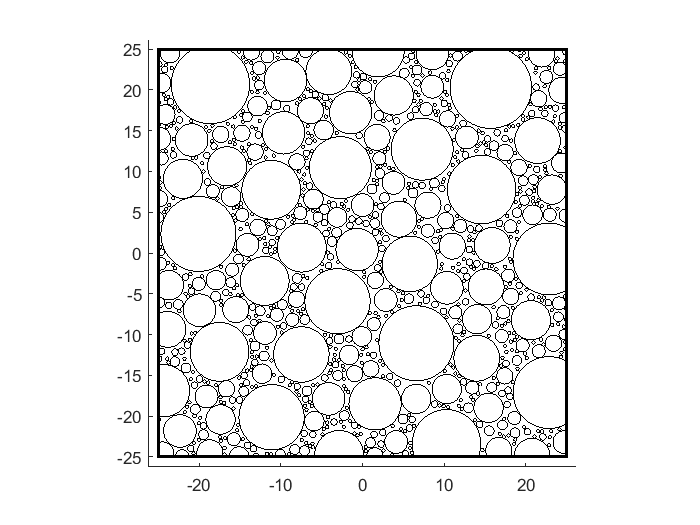

rng('default') % for reproducibility 
bubblebath()

## Specify radii

All parameters are optional and are defined along with their default values in the help section of `bubblebath`.  

### Specify a range of radii

Attempt to create circles from 3 radii (r) that span from r=1 to r=3.  Set flag to suppress internal warnings for the remaining examples.  

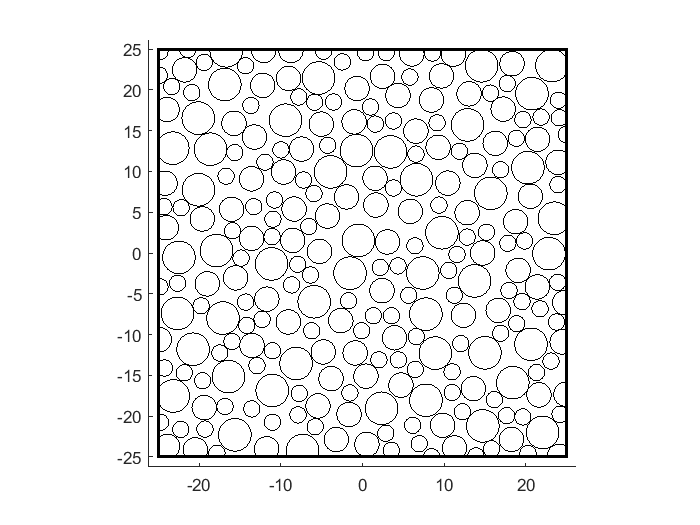

rng('default') % for reproducibility 
clear S
S.circSize = [1 2];
S.nSizes = 3;
S.supressWarning = true;
bubblebath(S)

### Specify a vector of radii

`nSizes` must be set to `NaN` when `circSize` is not a 1x2 range of radii.

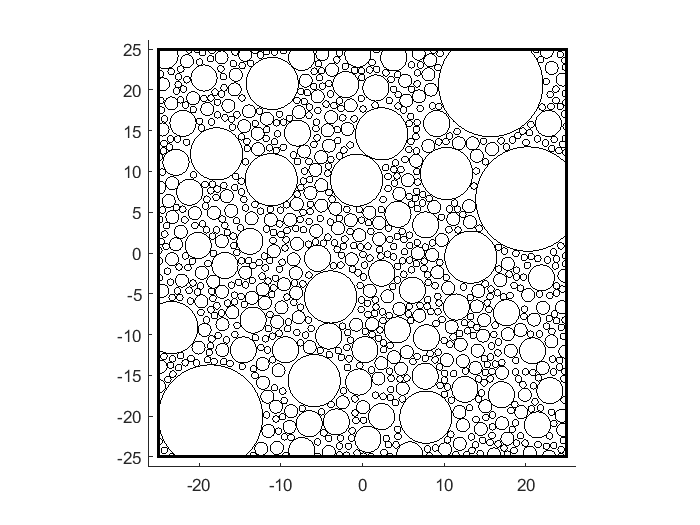

rng('default') % for reproducibility 
clear S
S.circSize = [0.4 0.8 1.6 3.2 6.4];
S.nSizes = NaN; 
S.supressWarning = true;
bubblebath(S)

### Specify a single radius

`nSize` must be set to `NaN` when `circSize` is not a 1x2 range of radii.

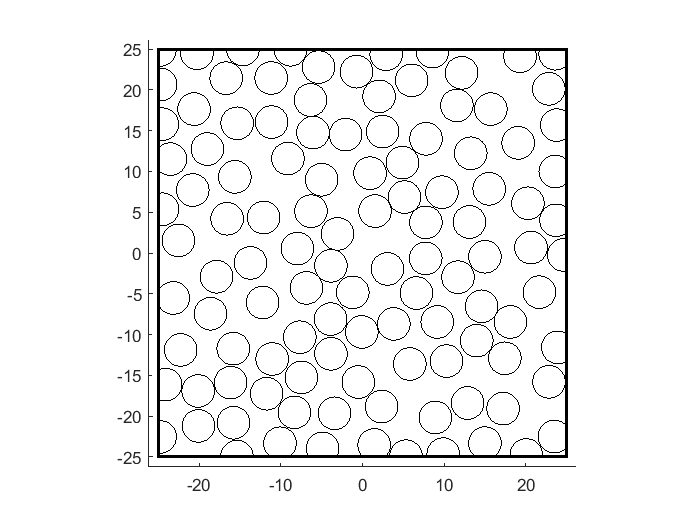

rng('default') % for reproducibility 
clear S
S.circSize = 2;
S.nSizes = NaN; 
S.supressWarning = true;
bubblebath(S)

## Specify frame size and bubble behavior at the frame edges

`edgeType` has 4 options.

- `edgeType=0` circles at the frame edges expand outside of the frame.

- `edgeType=1` all circles will be entirely within the frame. 

- `edgeType=2` circles are cut off by the frame.

- `edgeType=3` circles that intersect the frame are wrapped to the other side of the frame.

`frameSize` specifies the width and height of the frame, centered at (0,0).

`drawFrame` draws the rectangular frame when `true` (default) or does not draw the frame when `false`. 

`axisHandle` specifies the axis. 

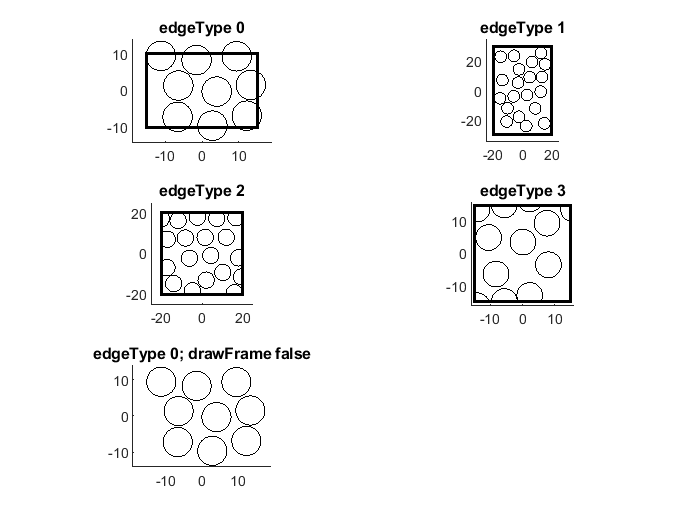

rng('default') % for reproducibility 
clear S
figure(); 
tiledlayout(3,2)
S.axisHandle = nexttile();
S.frameSize = [30,20];
S.circSize = 4; 
S.nSizes = NaN; 
S.edgeType = 0;
S.supressWarning = true;
bubblebath(S)
xlim(S.axisHandle, [-19 19])
ylim(S.axisHandle, [-14 14])
title(S.axisHandle, 'edgeType 0')

S.axisHandle = nexttile();
S.frameSize = [40,60];
S.edgeType = 1;
bubblebath(S)
xlim(S.axisHandle, [-25 25])
ylim(S.axisHandle, [-35 35])
title(S.axisHandle, 'edgeType 1')

S.axisHandle = nexttile();
S.frameSize = [40 40];
S.edgeType = 2;
bubblebath(S)
xlim(S.axisHandle, [-25 25])
ylim(S.axisHandle, [-25 25])
title(S.axisHandle, 'edgeType 2')

S.axisHandle = nexttile();
S.frameSize = [30 30];
S.edgeType = 3;
bubblebath(S)
xlim(S.axisHandle, [-16 16])
ylim(S.axisHandle, [-16 16])
title(S.axisHandle, 'edgeType 3')

rng('default')
S.axisHandle = nexttile();
S.frameSize = [30 20];
S.circSize = 4; 
S.edgeType = 0;
S.drawFrame = false;
bubblebath(S)
xlim(S.axisHandle, [-19 19])
ylim(S.axisHandle, [-14 14])
title(S.axisHandle, 'edgeType 0; drawFrame false')

## Set `overlap` flag and `overlapType`

Overlap is specified by one of the following scalar values

- `overlap=true` circles can overlap by any amount.

- `overlap=false` circles will not overlap (default).

- `overlap=[a positive value]` sets the minimum distance between bubbles (see `overlapType`).

- `overlap=[a negative value]` sets the maximum overlap between bubbles (see `overlapType`).

OverlapType specifies how overlap is defined when `overlap` is a positive or negative numeric value.  

- `overlapType='absolute'` the `overlap` distance is the same for all radii. 

- `overlapType='relative'` the `overlap` distance is `r*overlap` where `r` is the radius (default).

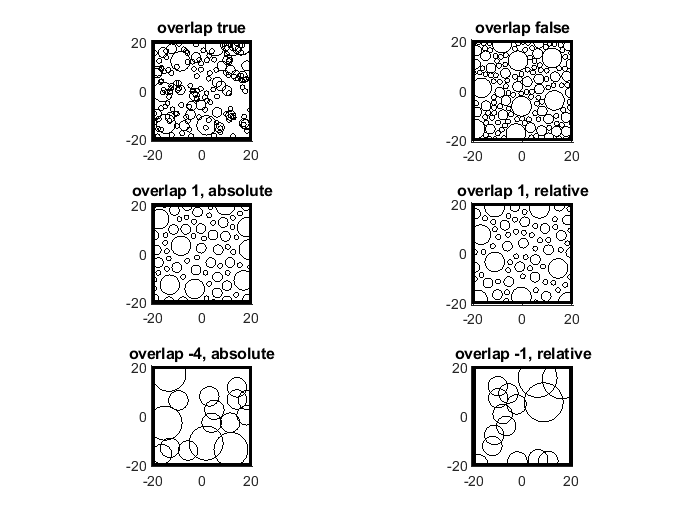

rng('default') % for reproducibility 
clear S
figure(); 
tiledlayout(3,2)
S.axisHandle = nexttile();
S.frameSize = [40 40];
S.circSize = [1 2 4]; 
S.nSizes = NaN; 
S.overlap = true; 
S.supressWarning = true;
bubblebath(S)
title(S.axisHandle, 'overlap true')

S.axisHandle = nexttile();
S.overlap = false; 
bubblebath(S)
title(S.axisHandle, 'overlap false')

S.axisHandle = nexttile();
S.overlap = 1; 
S.overlapType = 'absolute';
bubblebath(S)
title(S.axisHandle, 'overlap 1, absolute')

S.axisHandle = nexttile();
S.overlap = 1; 
S.overlapType = 'relative';
bubblebath(S)
title(S.axisHandle, 'overlap 1, relative')

S.axisHandle = nexttile();
S.circSize = [4,7]; 
S.overlap = -4; 
S.overlapType = 'absolute';
bubblebath(S)
title(S.axisHandle, 'overlap -4, absolute')

S.axisHandle = nexttile();
S.circSize = [4,8]; 
S.overlap = -1; 
S.overlapType = 'relative';
bubblebath(S)
title(S.axisHandle, 'overlap -1, relative')

## Set density

Density is value [0 < density <= 1] with a default of 0.7 and controls the density of bubbles.  Note that there is a ceiling effect that prevents an increase in density as the plot becomes saturated with bubbles.

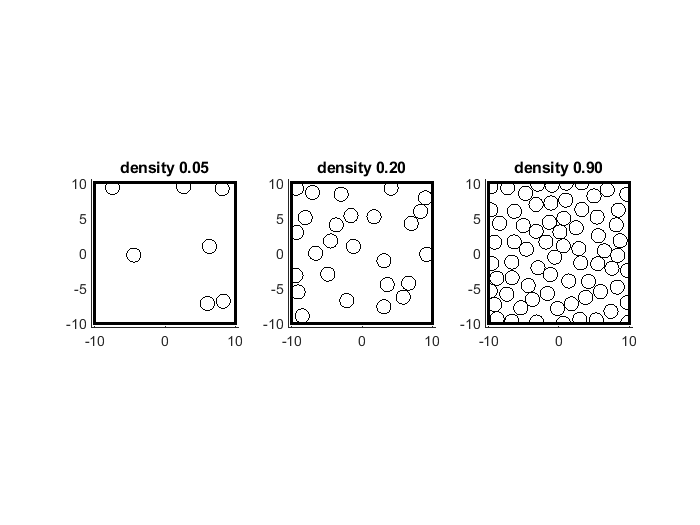

rng('default') % for reproducibility 
clear S
figure(); 
tiledlayout(1,3)
S.axisHandle = nexttile();
S.frameSize = [20 20];
S.circSize = 1; 
S.nSizes = NaN; 
S.density = .05; 
S.supressWarning = true;
bubblebath(S)
title(S.axisHandle, 'density 0.05')

S.axisHandle = nexttile();
S.density = .20;  
bubblebath(S)
title(S.axisHandle, 'density 0.20')

S.axisHandle = nexttile();
S.density = .90;  
bubblebath(S)
title(S.axisHandle, 'density 0.90')

## Control speed and number of attempts

The algorithm makes iterative attempts the set randomized circles while meeting the parameter specifications.  The following parameters will affect the algorithm's speed and outcome. 

- `maxCircsPerRad` sets the maximum number of bubbles per radius (default 5000, unless the radii are small, this upper limit will rarely be met).

- `circPoints` sets the number of coordinates in each circle (default 628).  Reducing the value greatly decreases the size of the figure file.

- `maxIt` sets the maximum number of attempts to find available circle locations for each radius (default 200).  Increasing this value increases the chance of filling available space and increase the computation time.  

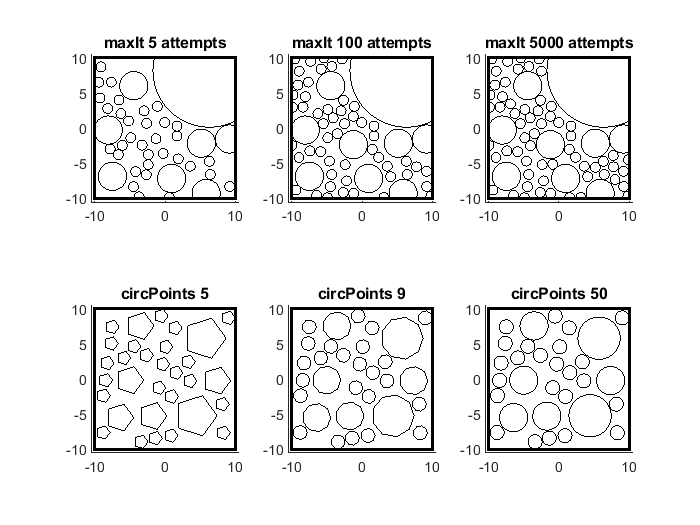

rng('default') % for reproducibility 
clear S
figure(); 
tiledlayout(2,3)
S.axisHandle = nexttile();
S.frameSize = [20 20];
S.circSize = [.7 2 8]; 
S.nSizes = NaN; 
S.maxIt = 5; 
S.supressWarning = true;
bubblebath(S)
title(S.axisHandle, 'maxIt 5 attempts')

rng('default')
S.axisHandle = nexttile();
S.maxIt = 100;
bubblebath(S)
title(S.axisHandle, 'maxIt 100 attempts')

rng('default')
S.axisHandle = nexttile();
S.maxIt = 3000;
bubblebath(S)
title(S.axisHandle, 'maxIt 5000 attempts')

rng('default')
S.axisHandle = nexttile();
S.circSize = [1,2,3];
S.circPoints = 5;
S.edgeType = 1;
S.maxIt = 200;
bubblebath(S)
title(S.axisHandle, 'circPoints 5')

rng('default')
S.axisHandle = nexttile();
S.circPoints = 9;
bubblebath(S)
title(S.axisHandle, 'circPoints 9')

rng('default')
S.axisHandle = nexttile();
S.circPoints = 50;
bubblebath(S)
title(S.axisHandle, 'circPoints 50')

## Use outputs

### Reproduce a bubblebath plot

Set the seed to the random number generator to reproduce a plot.  Due to algorithm changes between releases of `bubblebath.m`, reproducibility may require using the same version.

rng('shuffle')
figure()
tiledlayout(1,2)
clear S
S.axisHandle = nexttile();
S.supressWarning = true; 
[~, ~, ~, bbStruct] = bubblebath(S);

% reproduce plot
rng(bbStruct.rng)
bbStruct.axisHandle = nexttile();
bubblebath(bbStruct)

View parameters

disp(bbStruct)

        axisHandle: [1×1 Axes]
         frameSize: [50 50]
          circSize: [0.2 5]
            nSizes: 25
    maxCircsPerRad: 5000
        circPoints: 628
             maxIt: 200
          edgeType: 2
           density: 0.7
           overlap: 0
       overlapType: 'relative'
         drawFrame: 1
               rng: [1×1 struct]



### Calculate and plot the area of each circle

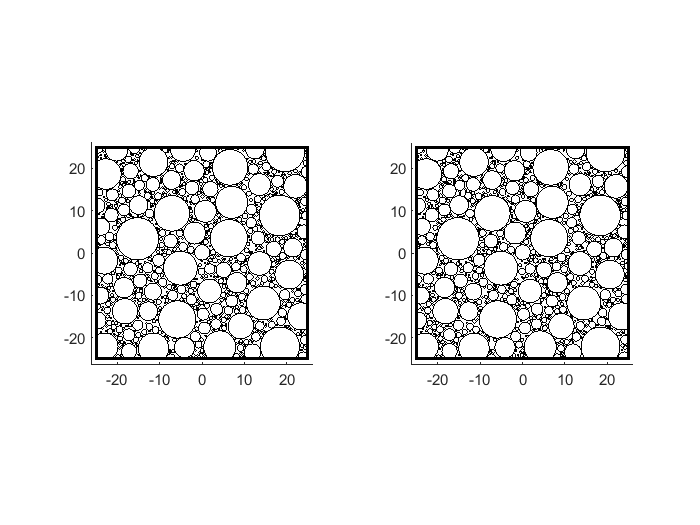

rng('default')
figure()
tiledlayout(1,2)
clear S
S.axisHandle = nexttile();
S.circSize = [2 4 8];
S.nSizes = NaN; 
S.edgeType = 1;
S.supressWarning = true;
circData = bubblebath(S); 

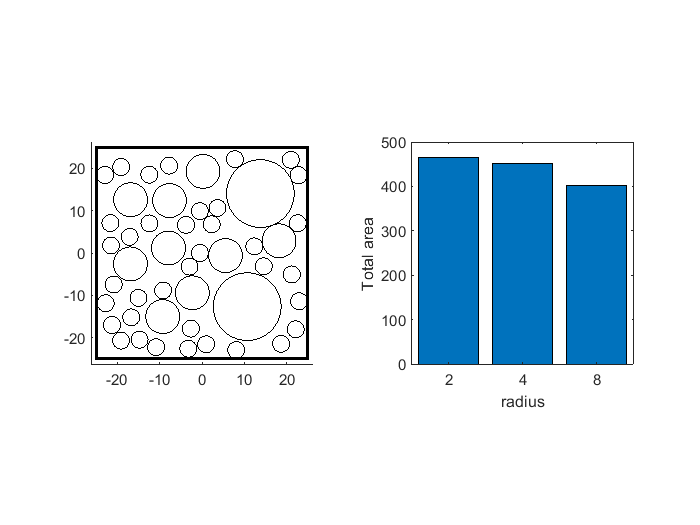


circArea = pi * circData(:,3).^2; 
[radiusID, radii] = findgroups(circData(:,3));
totalArea = splitapply(@sum,circArea,radiusID);
nexttile()
bar(categorical(radii), totalArea); 
axis square
xlabel('radius')
ylabel('Total area')

### Fill bubbles with color

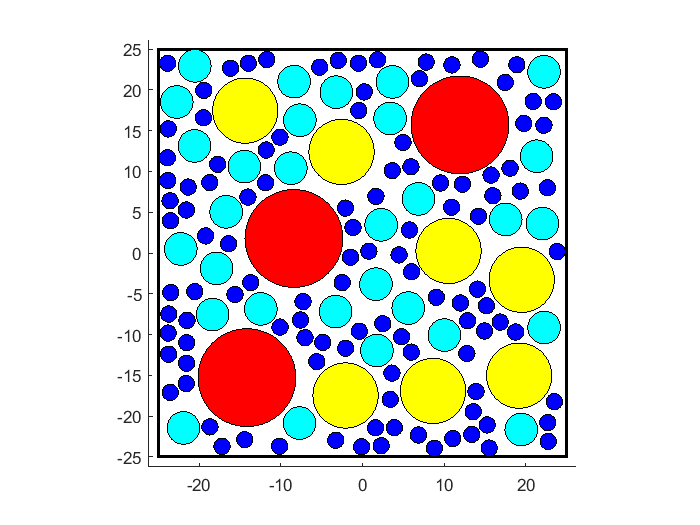

rng('default')
clear S
S.circSize = [1 2 4 6];
S.nSizes = NaN; 
S.edgeType = 1;
S.overlap = .2;
S.supressWarning = true;
[circData, circHandles] = bubblebath(S); 
radiusID = findgroups(circData(:,3));
colors = jet(max(radiusID)); 
arrayfun(@(i)rectangle('Position',[circData(i,1:2)-circData(i,3),circData(i,3).*[2,2]],...
    'FaceColor',colors(radiusID(i),:),'Curvature',[1,1]), 1:size(circData,1))
delete(circHandles)